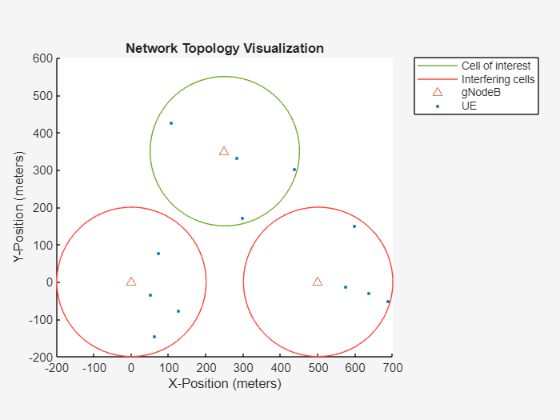

wirelessnetworkSupportPackageCheck
rng("default") % Reset the random number generator
numFrameSimulation = 20; % Simulation time in terms of number of 10 ms frames
networkSimulator = wirelessNetworkSimulator.init;
gNBPositions = [0 0 0; 500 0 0; 250 350 0];
gNBOfInterestIdx = 3; % Specify a value between 1 and number of gNBs
gNBs = nrGNB(Position=gNBPositions,CarrierFrequency=30e9, ...
    ChannelBandwidth=40e6,SubcarrierSpacing=60e3,TransmitPower=30,ReceiveGain=11);
for gNBIdx = 1:length(gNBs)
    % Resource allocation type value 0 indicate noncontiguous allocation of
    % frequency-domain resources in terms of RBGs
    configureScheduler(gNBs(gNBIdx),ResourceAllocationType=0)
end
numCells = length(gNBs);
cellRadius = 200; % Radius of each cell (in meters)
numUEsPerCell = 4;
uePositions = generateUEPositions(cellRadius,gNBPositions,numUEsPerCell);
UEs = cell(numCells,1);
for cellIdx = 1:numCells
    ueNames = "UE-" + (1:size(uePositions{cellIdx},1));
    UEs{cellIdx} = nrUE(Name=ueNames,Position=uePositions{cellIdx},ReceiveGain=11);
    connectUE(gNBs(cellIdx),UEs{cellIdx},FullBufferTraffic="DL")
end
addNodes(networkSimulator,gNBs);
for cellIdx = 1:numCells
    addNodes(networkSimulator,UEs{cellIdx})
end
cellOfInterest = gNBs(gNBOfInterestIdx).ID;
enableTraces = true;
linkDir = 0; % Indicates DL
if enableTraces
    simSchedulingLogger = cell(numCells,1);
    simPhyLogger = cell(numCells,1);

    for cellIdx = 1:numCells
        % Create an object for MAC DL scheduling traces logging
        simSchedulingLogger{cellIdx} = helperNRSchedulingLogger(numFrameSimulation, ...
            gNBs(cellOfInterest),UEs{cellOfInterest},LinkDirection=linkDir);

         % Create an object for PHY layer traces logging
        simPhyLogger{cellIdx} = helperNRPhyLogger(numFrameSimulation,gNBs(cellOfInterest), ...
            UEs{cellOfInterest});
    end
end
numMetricsSteps = numFrameSimulation;
metricsVisualizer = helperNRMetricsVisualizer(gNBs(cellOfInterest),UEs{cellOfInterest}, ...
    CellOfInterest=cellOfInterest,NumMetricsSteps=numMetricsSteps, ...
    PlotSchedulerMetrics=true,PlotPhyMetrics=true,LinkDirection=linkDir);
simulationLogFile = "simulationLogs"; % For logging the simulation traces
enableMobility = true;
if enableMobility
    ueSpeedRange = [1 100]; % In meters per second
    ueWithMobility = UEs{cellOfInterest}(2); % Get the UE-2 in the cell of interest
    % Install random waypoint mobility on the selected UE
    addMobility(ueWithMobility,SpeedRange=ueSpeedRange,BoundaryShape="circle",Bounds=[gNBs(cellOfInterest).Position(1:2) cellRadius])
end
helperTopologyVisualizer(cellOfInterest,cellRadius,gNBs,UEs)

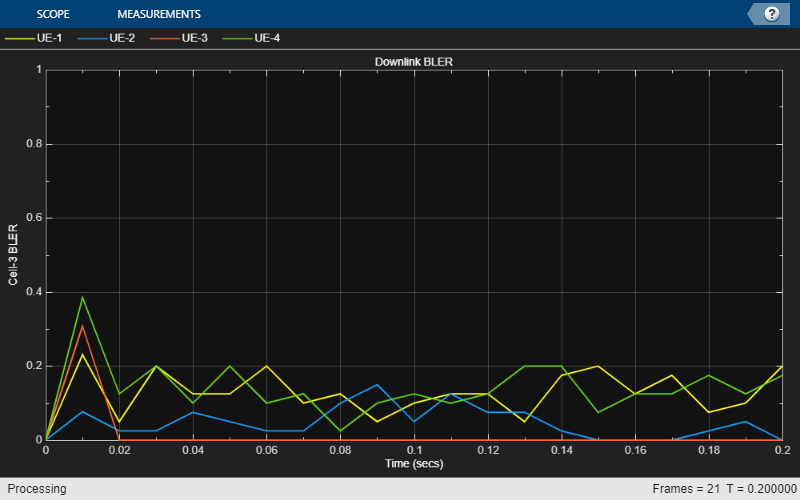

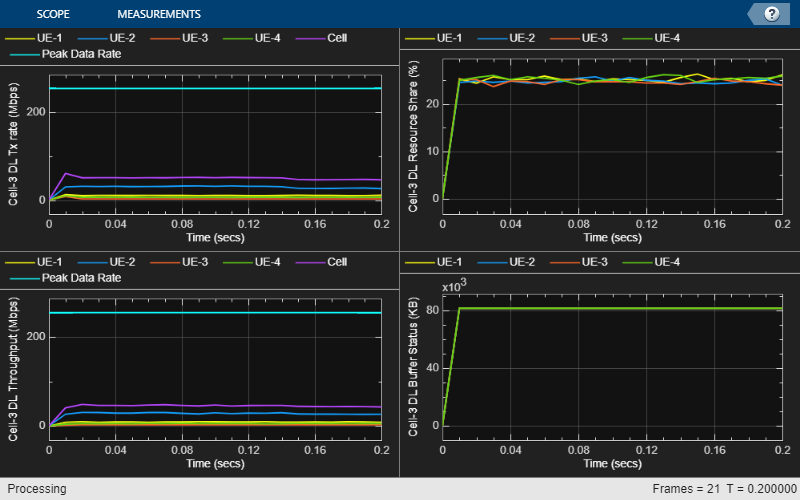

% Calculate the simulation duration (in seconds)
simulationTime = numFrameSimulation*1e-2;
% Run the simulation
run(networkSimulator,simulationTime);

gNBStats = statistics(gNBs);
ueStats = cell(numCells, 1);
for cellIdx = 1:numCells
    ueStats{cellIdx} = statistics(UEs{cellIdx});
end
displayPerformanceIndicators(metricsVisualizer)

Peak DL Throughput: 253.83 Mbps. Achieved Cell DL Throughput: 45.11 Mbps
Achieved DL Throughput for each UE: [9.01        28.13         2.64         5.33]
Peak DL spectral efficiency: 6.35 bits/s/Hz. Achieved DL spectral efficiency for cell: 1.13 bits/s/Hz
Block error rate for each UE in the downlink direction: [0.133       0.049       0.015       0.145]



if enableTraces
    % Get the logs
    simulationLogs = cell(numCells, 1);
    for cellIdx = 1:numCells
        if gNBs(cellIdx).DuplexMode == "FDD"
            logInfo = struct("NCellID",[],"DLTimeStepLogs",[], ...
                "SchedulingAssignmentLogs",[],"PhyReceptionLogs",[]);
            logInfo.DLTimeStepLogs = getSchedulingLogs(simSchedulingLogger{cellIdx});
        else % TDD
            logInfo = struct("NCellID",[],"TimeStepLogs",[], ...
                "SchedulingAssignmentLogs",[],"PhyReceptionLogs",[]);
            logInfo.TimeStepLogs = getSchedulingLogs(simSchedulingLogger{cellIdx});
        end
        logInfo.NCellID = gNBs(cellIdx).ID;
        % Get the scheduling assignments log
        logInfo.SchedulingAssignmentLogs = getGrantLogs(simSchedulingLogger{cellIdx});
        % Get the Phy reception logs
        logInfo.PhyReceptionLogs = getReceptionLogs(simPhyLogger{cellIdx});
        simulationLogs{cellIdx} = logInfo;
    end
    % Save simulation logs in a MAT-file
    save(simulationLogFile,"simulationLogs")
end

function uePositions = generateUEPositions(cellRadius,gNBPositions,numUEsPerCell)
%generateUEPositions Return the position of UEs in each cell

numCells = size(gNBPositions,1);
uePositions = cell(numCells,1);
for cellIdx=1:numCells
    gnbXCo = gNBPositions(cellIdx,1); % gNB X-coordinate
    gnbYCo = gNBPositions(cellIdx,2); % gNB Y-coordinate
    gnbZCo = gNBPositions(cellIdx,3); % gNB Z-coordinate
    theta = rand(numUEsPerCell,1)*(2*pi);
    % Expression to calculate position of UEs with in the cell. By default,
    % it will place the UEs randomly with in the cell
    r = sqrt(rand(numUEsPerCell,1))*cellRadius;
    x = round(gnbXCo + r.*cos(theta));
    y = round(gnbYCo + r.*sin(theta));
    z = ones(numUEsPerCell,1) * gnbZCo;
    uePositions{cellIdx} = [x y z];
end
end